In this tutorial, we extended JSNMF to analyze single-cell multi-omics data with more than two modalities measured from the same single cell. A scNMT-seq dataset generated from the developing mouse embryo, where gene expression,  chromatin accessibility and methylation were profiled simultaneously in the same cell

addpath(genpath('../data'))
addpath('../codes')
addpath('../external')

Load three modalities scNMT-seq data

load('genebody.mat')
X1 = rna; X2 = acc; X3 = met;

load('stage_lineage.mat')
[label_name, I] = sort(stage_lineage_2);
label_name = strrep(label_name,'_','\_');
num_clu = length(unique(label_name));


tag = unique(label_name);
tag = cellstr(tag);
[~, label] = ismember(label_name,tag);

[alpha, gamma, Inits] = pa_sel(X1, X2, X3, num_clu);
[~,~,~,H1,H2,H3,S,iter,objs] = jsnmf_3mod(X1,X2,X3,alpha,gamma,Inits);

iteration starts!
number of iteration:10  obj:16161948.1468
number of iteration:20  obj:15936813.377
number of iteration:30  obj:15870628.7942
number of iteration:40  obj:15839232.4395
number of iteration:50  obj:15820792.2577
number of iteration:60  obj:15808549.3579
number of iteration:70  obj:15799735.1604
number of iteration:80  obj:15793012.4302
number of iteration:90  obj:15787667.1533
number of iteration:100  obj:15783283.6795
number of iteration:110  obj:15779601.2306
number of iteration:120  obj:15776447.356
number of iteration:130  obj:15773703.6129
number of iteration:140  obj:15771286.3463
number of iteration:150  obj:15769134.138
number of iteration:160  obj:15767200.5378
number of iteration:170  obj:15765449.8243
converged!


Can not reach host ":80  because ":  Connection refused: connect
Can not reach host "cgworkspace.cytogenie.org:80  because ":  杩欐槸鍦ㄤ富鏈哄悕瑙ｆ瀽鏃堕�氬父鍑虹幇鐨勬殏鏃堕敊璇紝瀹冩剰鍛崇潃鏈湴鏈嶅姟鍣ㄦ病鏈変粠鏉冨▉鏈嶅姟鍣ㄤ笂鏀跺埌鍝嶅簲銆� (cgworkspace.cytogenie.org)
Can not reach host "drive.google.com:80  because ":  connect timed out
Can not reach host "54.39.2.45:80  because ":  connect timed out


Parallelizing UMAP with MATLAB's 16 assigned logical cores for nn_descent_tasks, sgd_tasks
 Running basic (ub) reduction, v2.1.3
(ub=basic, us=supervised, ubt=template, ust=supervised template)


UMAP(method=MEX, n_neighbors=6, n_components=2, metric='precomputed', n_epochs=[], learning_rate=1, init=spectral, min_dist=0.38, spread=1, set_op_mix_ratio=1, local_connectivity=1, repulsion_strength=1, negative_sample_rate=5, transform_queue_size=4, a=0.80848864020896, b=1.20041126547991, randomize=true, target_n_neighbors=-1, target_metric='categorical', target_metric_kwds=[], target_weight=0.5, verbose=true, initial_alpha=1, sparse_data=false, small_data=true, distance_func='precomputed', dist_args=[]


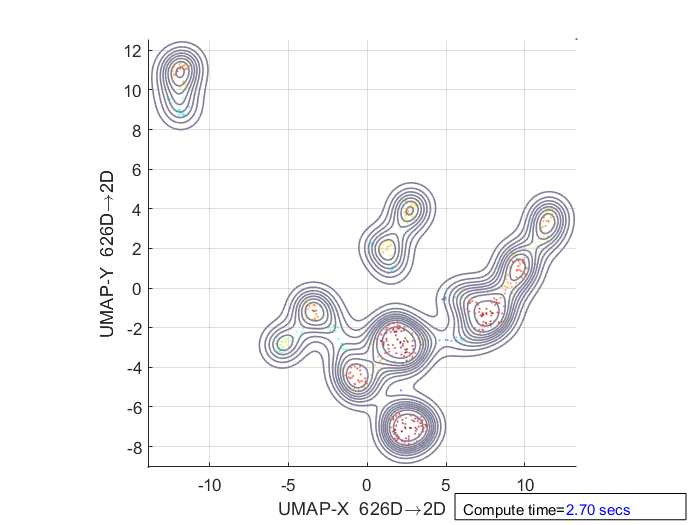

UMAP reduction finished (cost 2.71 secs)
 Finished basic (ub) reduction




%% Visualization with UMAP
addpath('../umapFileExchange/umap')
addpath('../umapFileExchange/util')

term = '.'; 
colors = generateColors(max(length(unique(label_name))),length(unique(term)));

D_jsnfm = 1-S; D_jsnfm = D_jsnfm-diag(diag(D_jsnfm));
[reduction_jsnmf, ~, ~, ~]=run_umap(D_jsnfm,'metric','precomputed','min_dist',0.38,'n_neighbors',6); 

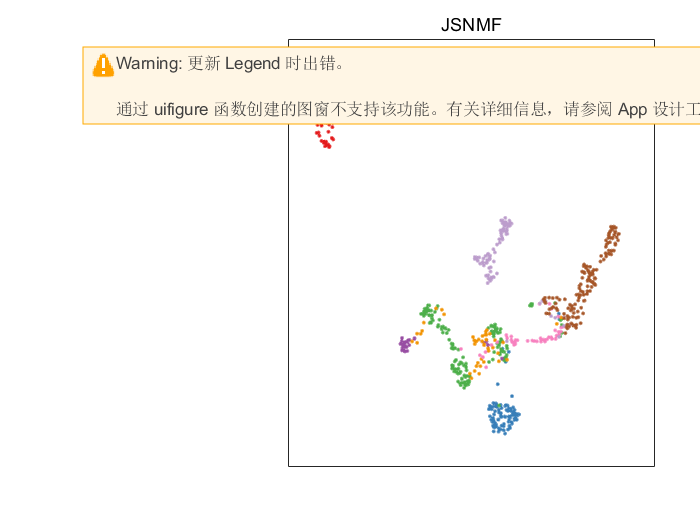

reduction_jsnmf = reduction_jsnmf(I,:);
gscatter(reduction_jsnmf(:,1),reduction_jsnmf(:,2),label_name,colors,[],6);
set(gca,'xtick',[],'ytick',[]);
title('JSNMF')

legend('Location','westoutside','Box','off','FontSize',9.5); 
legendmarkeradjust(16)
legend('boxoff')